clear;

% Load ROS bag
dataPath = "E:\ICRA2\radar_high_res\2020-07-13-14-10-09.bag";
% dataPath = "E:\ICRA2\radar_high_res\2020-07-13-14-07-37.bag";
bag = rosbag(dataPath);

% Extract images and view one 
images = select(bag, "MessageType", "sensor_msgs/Image", "Topic", "/camera/color/image_raw");
image1 = readMessages(images, [1], "DataFormat","struct");
imshow(rosReadImage(image1{1, 1}))

outputVideo = VideoWriter('output_video.mp4', 'MPEG-4');
outputVideo.FrameRate = 30;  % Adjust frame rate as needed
outputVideo.Quality = 90;    % Adjust quality as needed
open(outputVideo);

for i = 1:numel(image1)
    currentCell = image1{i, 1};
    writeVideo(outputVideo, rosReadImage(currentCell));
end 
close(outputVideo);

% Extract radar data 
radars = select(bag, "MessageType", "mmWave/data_frame", "Topic", "/radar_data");
radar1 = readMessages(radars, "DataFormat","struct");

% % Data cube 3
% dataCube = build_data_cube_3(radar1{1, 1}.Data, 304, 4, 2, 256); 
% disp(size(dataCube));

   128   304     2     4



% dataCube = squeeze(dataCube(:, :, :, 1));
% disp(size(dataCube));

   128   304     2



% nfft_r = 2^nextpow2(size(dataCube, 2));
% rangeProc = fft(dataCube(:, :, :), nfft_r, 2);
% disp(size(rangeProc));

   128   512     2



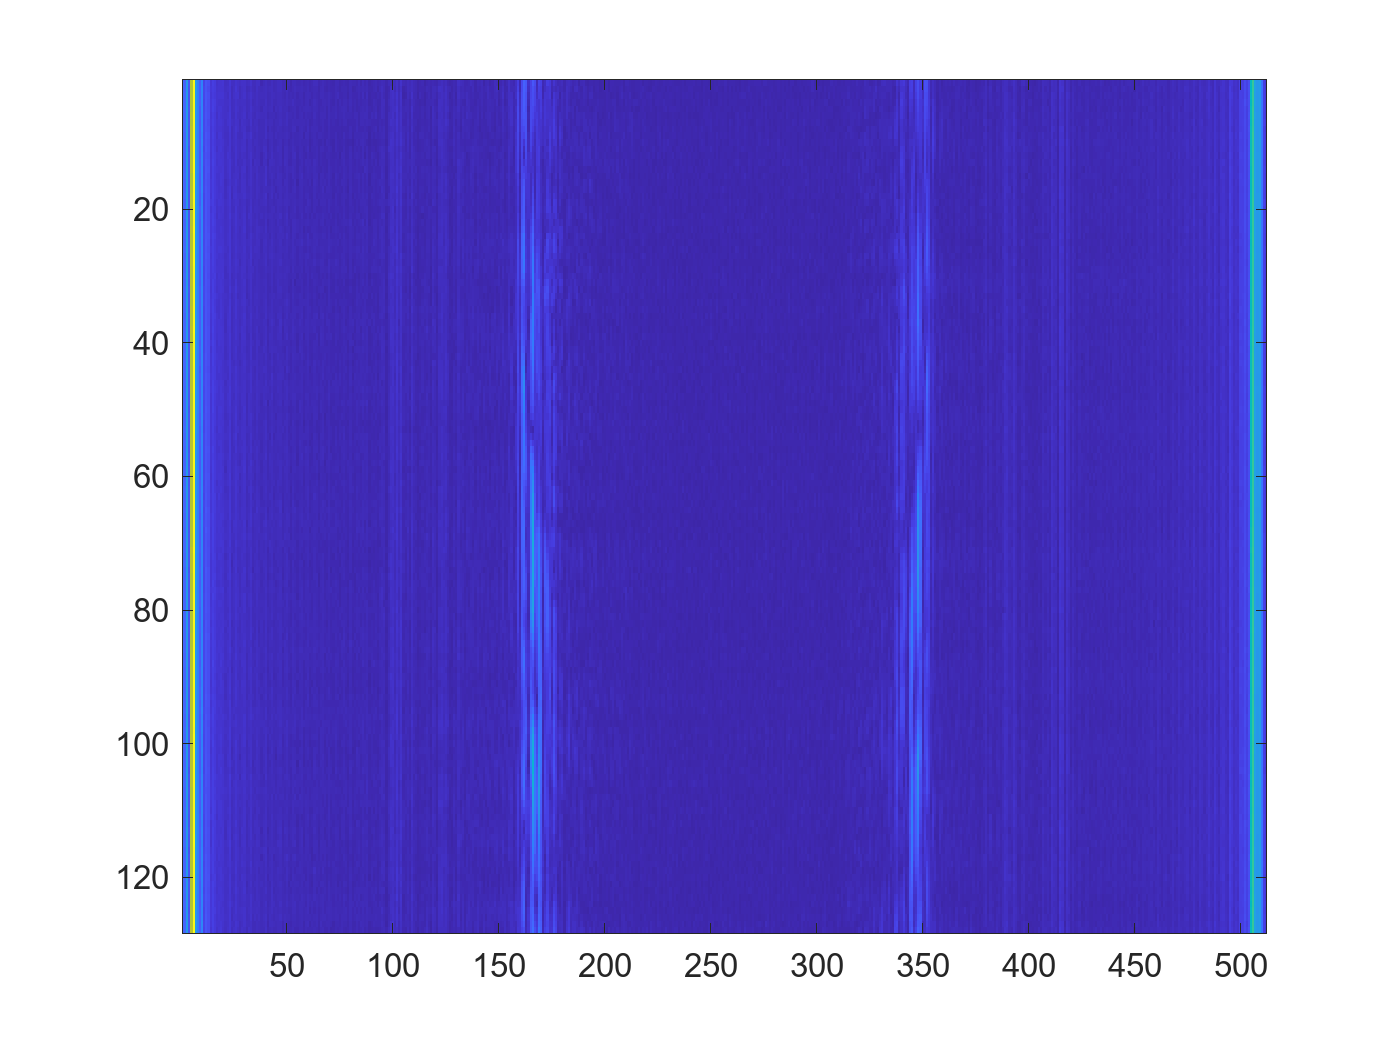

% imagesc(abs(rangeProc(:, :, 1)));

% Data cube 4
dataCube = build_data_cube_4(radar1{1, 1}.Data, 304, 4, 2, 256, 4); 
disp(size(dataCube));

   128   304     4     2



dataCube = squeeze(dataCube(:, :, :, 1));
disp(size(dataCube));

   128   304     4



nfft_r = 2^nextpow2(size(dataCube, 2));
rangeProc = fft(dataCube(:, :, :), nfft_r, 2);
disp(size(rangeProc));

   128   512     4



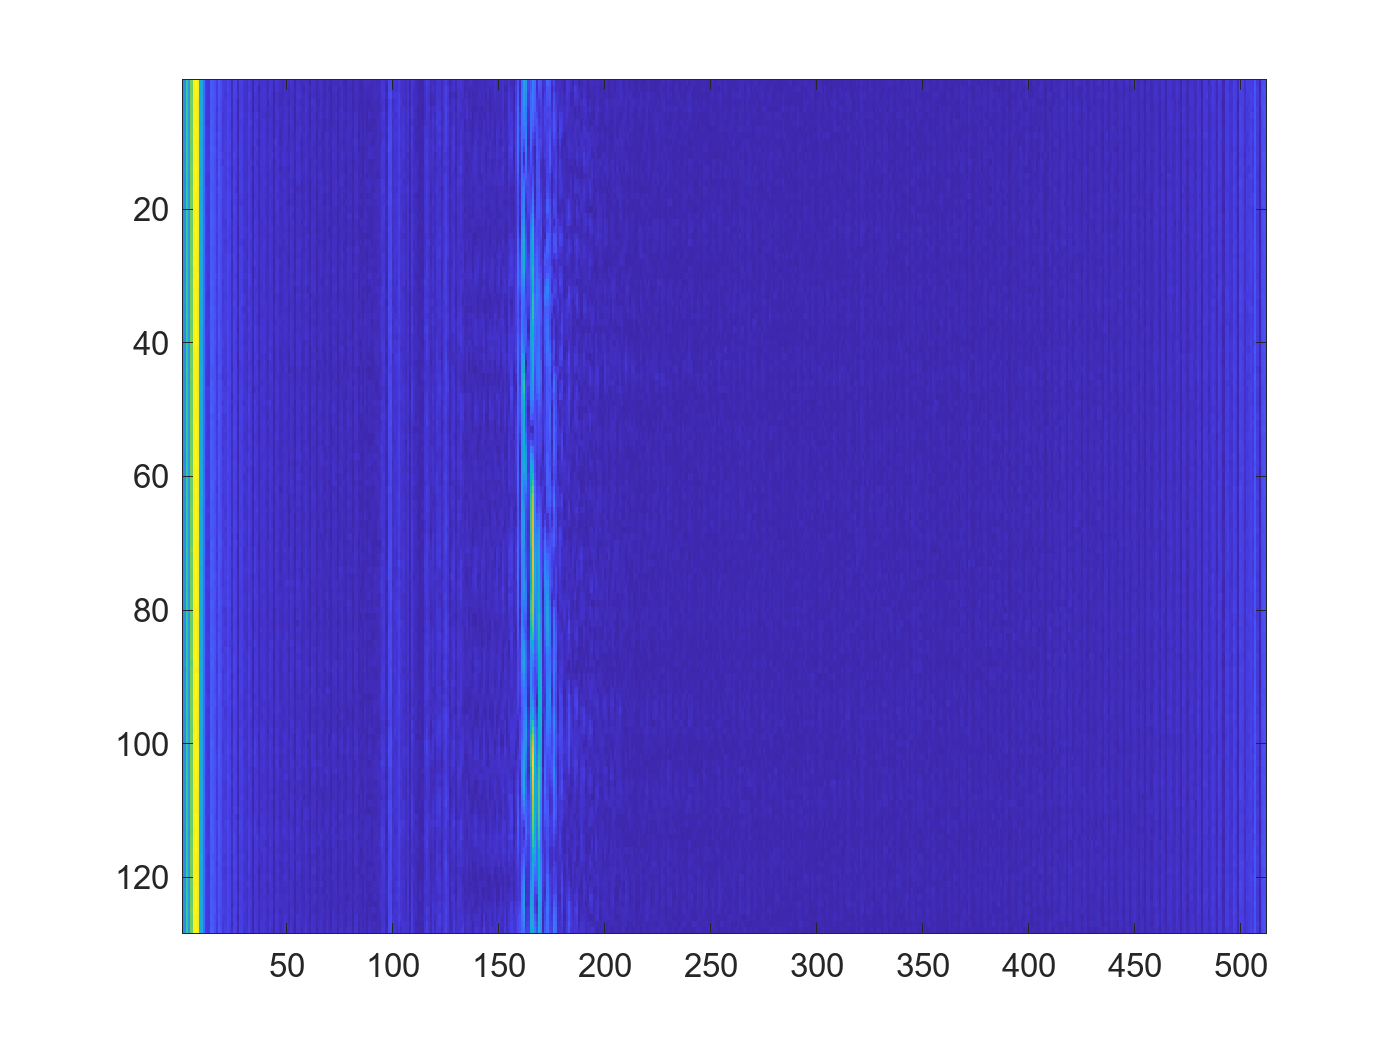

imagesc(abs(rangeProc(:, :, 1)));

dataCube = permute(dataCube, [2, 3, 1]);

% dataCube = build_data_cube_2(radar1{1, 1}.Data, 304, 4, 2, 256);
% nfft_r = 2^nextpow2(size(dataCube, 3));
% nfft_d = 2^nextpow2(size(dataCube, 2));
% 
% size(dataCube)
% dataMat = squeeze(dataCube(1, :, :));
% dataMat = permute(dataMat, [2, 1]);
% size(dataMat)
% 
% rangeProc = fft(dataMat, nfft_r, 1);
% imagesc(abs(rangeProc))
% dopProc = fft(rangeProc, nfft_d, 2);
% size(rangeProc)
% imagesc(abs(dopProc))

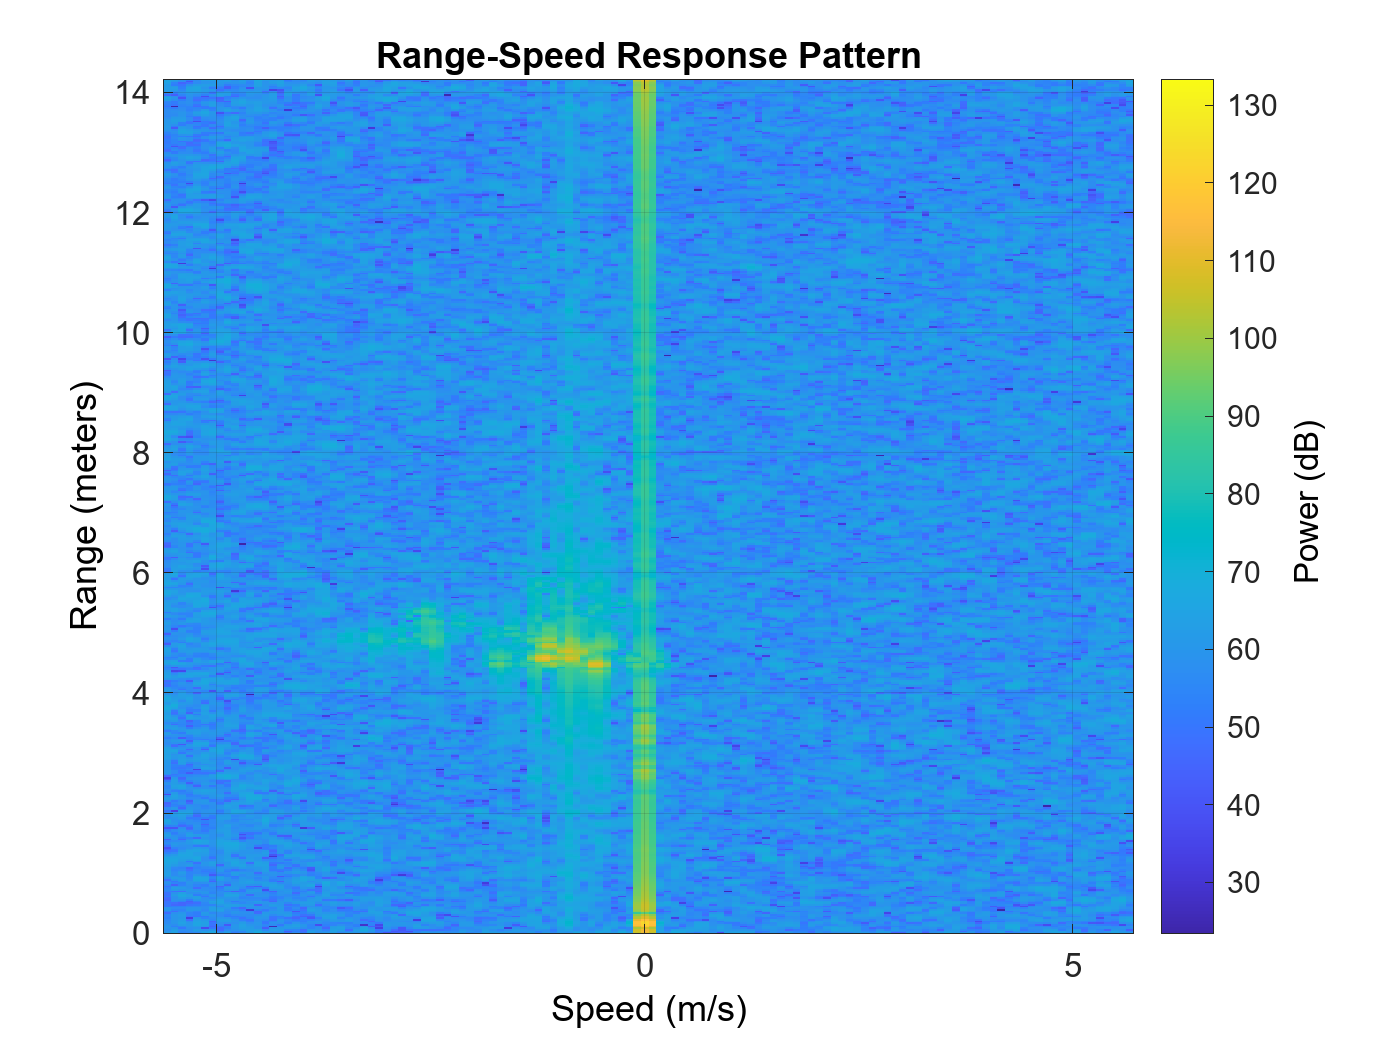


% Range processing 
nfft_r = 2^nextpow2(size(dataCube, 1));
c = physconst('LightSpeed');
fs = 9499000.0;
fc = 77e9;
ramp_end_time = 3.668e-05;
idle_time = 0.000135;
tm = ramp_end_time + idle_time;
PRF = 1 / tm;
sweepSlope = 100000000000000.0;
nfft_d = 2^nextpow2(size(dataCube, 3));

rngdop = phased.RangeDopplerResponse('PropagationSpeed',c,...
    'DopplerOutput','Speed','OperatingFrequency',fc,'SampleRate',fs,...
    'RangeMethod','FFT','PRFSource','Property',...
    'RangeWindow','Hann','PRF',PRF,...
    'SweepSlope',sweepSlope,...
    'RangeFFTLengthSource','Property','RangeFFTLength',nfft_r,...
    'DopplerFFTLengthSource','Property','DopplerFFTLength',nfft_d,...
    'DopplerWindow','Hann', ReferenceRangeCentered=0);

% dataCube = build_data_cube(radar1{1, 1}.Data, 304, 4, 2, 256);
% 
% dataSlice = dataCube(:, 1, 1);
% plot(abs(dataSlice))
% 
% fftd = fft(dataSlice);
% plot(abs(fftd))

plotResponse(rngdop, squeeze(dataCube(:, 1, :)));

dataCube2 = build_data_cube(radar1{1000, 1}.Data, 304, 4, 2, 256);

plotResponse(rngdop, squeeze(dataCube2(:, 1, :)));
[resp, r, sp] = rngdop(dataCube2);

testimg = image(uint8(log(abs(squeeze(resp(:, 1, :))))))

outputRadar = VideoWriter('radar_rd.mp4', 'MPEG-4');
outputRadar.FrameRate = 30;  % Adjust frame rate as needed
outputRadar.Quality = 90;    % Adjust quality as needed
open(outputRadar);


for i = 1:numel(radar1)
    currentCell = radar1{i, 1};
    % Process radar data 
    dataCube = build_data_cube(currentCell.Data, 304, 4, 2, 256);
    [resp, r, sp] = rngdop(dataCube);

    writeVideo(outputRadar, (uint8(log(abs(squeeze(resp(:, 1, :)))))));
end 
close(outputRadar);


% 
% % rd_results = cell(1, N_frames);
% 
% 
% 
% plotResponse(rngdop, squeeze(dataCube(:, 1, :)));
% 
% 
% figure
% imagesc(sp,r,abs(squeeze(resp(:, 1, :))));
% xlabel('Velocity (m/s)');
% ylabel('Range (m)');
% title('meaned - Range-Doppler Map');